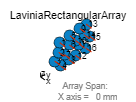


% MATLAB Code from Sensor Array Analyzer App

% Generated by MATLAB 9.11 and Phased Array System Toolbox 4.6

% Generated on 20-Apr-2022 17:45:57

% Create an arbitrary geometry array
Array = phased.ConformalArray();
Array.ElementPosition = [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;-0.25 -0.27 -0.35 -0.235 -0.05 -0.06 -0.16 -0.065 0.15 0.065 0.135 0.065 0.275 0.235 0.35 0.27;0.255 0.075 -0.045 -0.22 0.255 0.075 -0.045 -0.22 0.255 0.075 -0.045 -0.22 0.255 0.075 -0.045 -0.22];
Array.ElementNormal = [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
Array.Taper = 1;

% Create an omnidirectional microphone element
Elem = phased.OmnidirectionalMicrophoneElement;
Elem.FrequencyRange = [20 20000];
Elem.BackBaffled = false;
Array.Element = Elem;
% Create Figure

[dir, fname,~] = fileparts(matlab.desktop.editor.getActiveFilename);

save(dir + "\Arrays\" + fname + ".mat", "Array")

% % Plot Array Geometry
simulation.viewSensorArray3D(Array, fname)